# Stereo Microphone Array

## Input Arguments

MicSpacing = 0.20; %Distance between mics
YMicSpacing = 0.1; %Distance between Both Layers of Mics
isfourchan = true%Uses four microphones (default false - 2 microphones)

isfourchan = logical
   1


MicAngle = 100; %Angle between mics
ArrayName = ' ORTF Surround';

## Assign Frequencies and Propagation Speed

Frequency = 1000; %Test Frequency
PropagationSpeed = 344; %Speed of Sound

## Create a geometry array from microphone positions

Array = phased.ConformalArray();%Create Microphone Array Element
if isfourchan == true
    Array.ElementPosition = [(YMicSpacing/2) -(YMicSpacing/2) (YMicSpacing/2) -(YMicSpacing/2);-(MicSpacing/2) -(MicSpacing/2) (MicSpacing/2) (MicSpacing/2);0 0 0 0]; %Create position matrix for each microphone
    Array.ElementNormal = [-(MicAngle/2) -(180 - (MicAngle/2)) (MicAngle/2) (180 - (MicAngle/2));0 0 0 0]; %Create angle matrix for each microphone
elseif isfourchan == false
    Array.ElementPosition = [0 0;-(MicSpacing/2) (MicSpacing/2);0 0];
    Array.ElementNormal = [-(MicAngle/2) (MicAngle/2);0 0]; %Create angle matrix for each microphone
end


## Create a custom microphone element

CardMic = phased.CustomMicrophoneElement; %Create Cardioid Microphone Element
CardMic.FrequencyVector = [0 1e+20]; %Set Frequency Response to Audible spectrum
CardMic.FrequencyResponse = [0 0]; %Assign a Flat Frequency Responce
CardMic.PolarPatternFrequencies = [125 1000]; %Polar Response Set Frequencies
CardMic.PolarPatternAngles = [-180:1:180]; %Polar Response Angles
CardMic.PolarPattern = mag2db([...
    0.6+0.4*cosd(CardMic.PolarPatternAngles);... %Polar Response at 125hz
    0.5+0.5*cosd(CardMic.PolarPatternAngles)]); %Polar Response at 1kHz


Array.Element = CardMic;

## Find the weights

w = ones(getNumElements(Array), length(Frequency));

## Array ICTD and ICLD

ICTD

ICTDTable = zeros(73,37); % ITD Values Table
[aziLength,eleLength] = size(ICTDTable); % Size of Table
ICTD = phased.ElementDelay('SensorArray',Array, 'PropagationSpeed', PropagationSpeed); % Time delay of each microphone element

% ICLD
ICLDTable = zeros(73,37); % Store ITD Values

for a = 1:aziLength % Each Azimuth Angle
    for e = 1:eleLength %Each Elevation Angle
        ang = [a*5 - 185;e*5 - 95]; % Current source angle
        
        ICTD_ae = ICTD(ang); % Get tau
        resp = Array([31.5,63,125, 250, 500, 1000, 2000, 4000, 8000, 16000], ang); %Source Frequency, Source Angle
        resp = sum(resp, [2 3]); % Get summed level of left and right channel
        if isfourchan == true
            ICTDTable(a,e) = ((ICTD_ae(1) + ICTD_ae(2)) - (ICTD_ae(3) + ICTD_ae(4)))/2; % Calculate time difference
            ICLDTable(a,e) = mag2db((resp(3) + resp(4))/(resp(1) + resp(2))); %Get ICLD
        elseif isfourchan == false
            ICTDTable(a,e) = (ICTD_ae(1) - ICTD_ae(2)); % Calculate time difference
            ICLDTable(a,e) = mag2db(resp(2)/resp(1)); %Get ICLD
        end
       
    end
end

## Values

maxICTD = max(ICTDTable)

maxICTD = 	1.0e+-3 *

         0    0.0507    0.1010    0.1505    0.1988    0.2457    0.2907    0.3335    0.3737    0.4111    0.4454    0.4763    0.5035    0.5269    0.5463    0.5616    0.5726    0.5792    0.5814    0.5792    0.5726    0.5616    0.5463    0.5269    0.5035    0.4763    0.4454    0.4111    0.3737    0.3335    0.2907    0.2457    0.1988    0.1505    0.1010    0.0507         0


maxICLD = max(ICLDTable)

maxICLD =          0    0.9925    1.9867    2.8591    3.7352    4.7417    5.7553    6.5206    7.4115    8.3248    9.1058    9.8910   10.6795   11.2064   11.7337   12.2608   12.5240   12.7868   12.7868   12.7868   12.5240   12.2608   11.7337   11.2064   10.6795    9.8910    9.1058    8.3248    7.4115    6.5206    5.7553    4.7417    3.7352    2.8591    1.9867    0.9925         0


## Create Figure

figure(1)

## Plot 2D Polar Plot

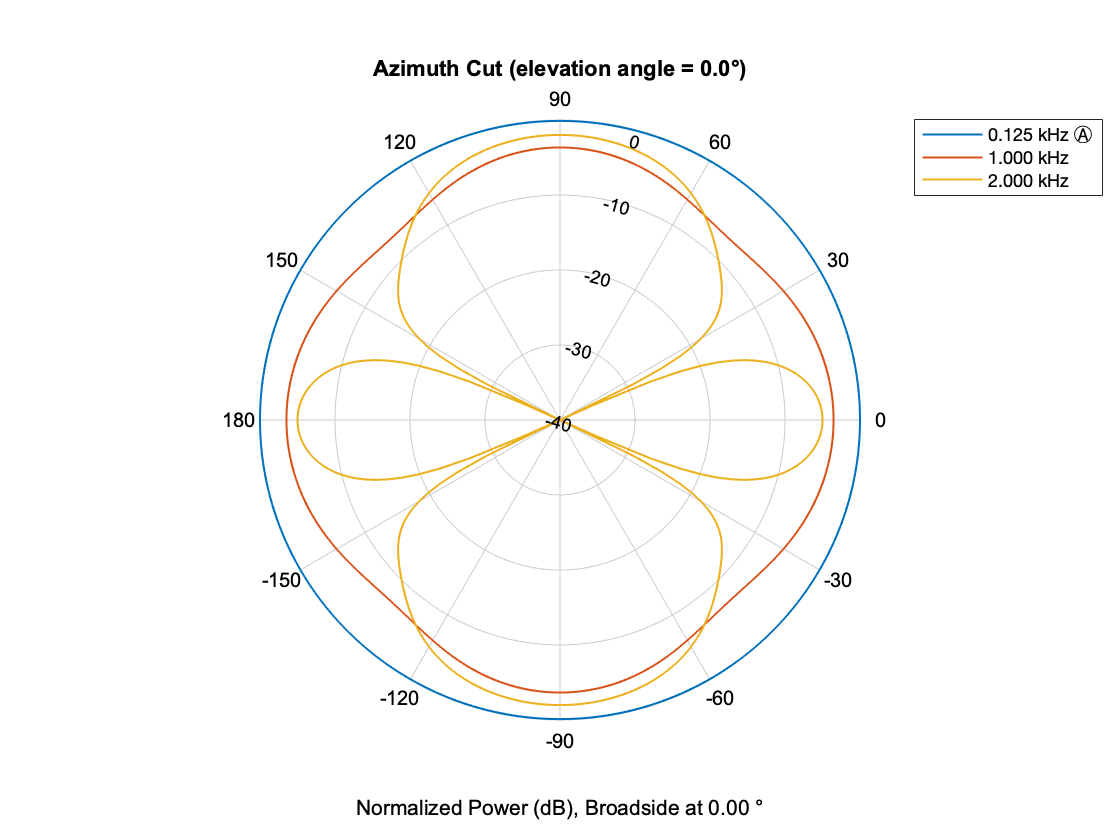

format = 'polar';
plotType = 'powerdb';
plotStyle = 'Overlay';
%subplot(1,2,1)
pattern(Array, [125, 1000, 2000], -180:180, 0, 'PropagationSpeed', PropagationSpeed,...
    'CoordinateSystem', format ,'weights', w, ...
    'Type', plotType, 'PlotStyle', plotStyle);

## Plot 2D Polar Plot

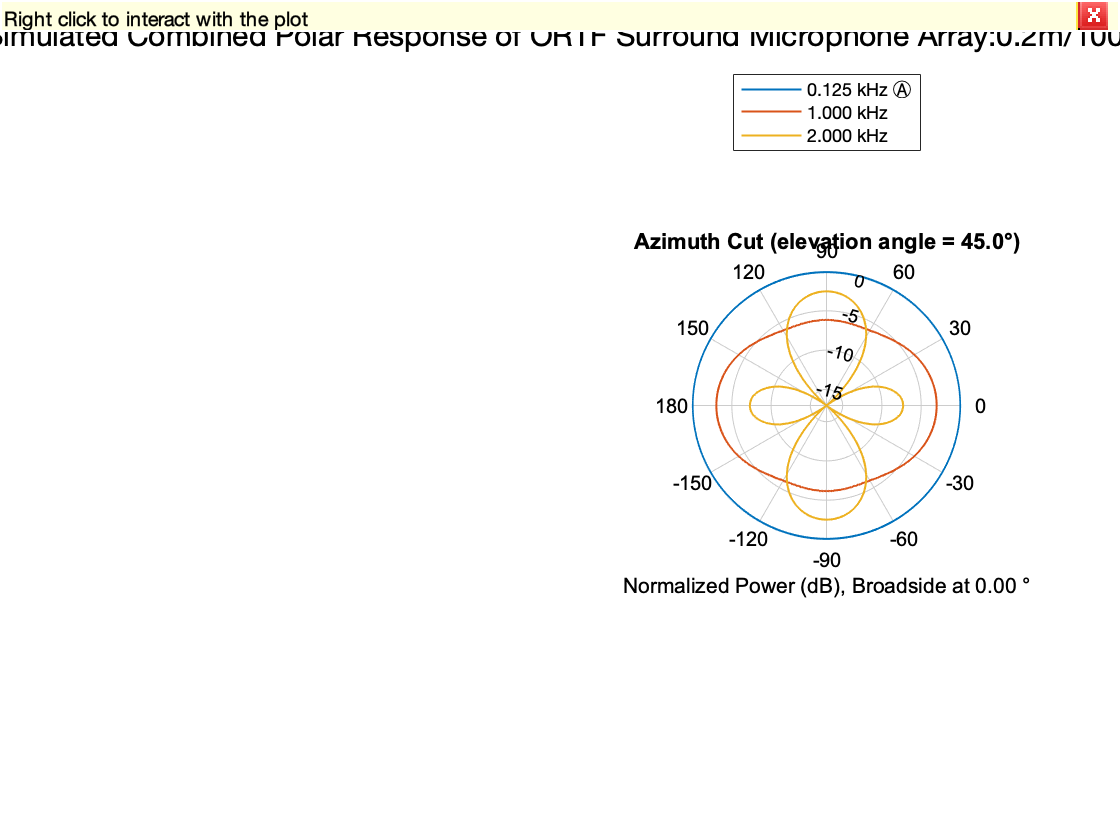

format = 'polar';
cutAngle = 45;
plotType = 'powerdb';
plotStyle = 'Overlay';
subplot(1,2,2)
pattern(Array, [125, 1000, 2000], -180:180, cutAngle, 'PropagationSpeed', PropagationSpeed,...
    'CoordinateSystem', format ,'weights', w, ...
    'Type', plotType, 'PlotStyle', plotStyle);
sgtitle(strcat('Simulated Combined Polar Response of', ' ', ArrayName, ' Microphone Array:', ' ', string(MicSpacing), 'm/', string(MicAngle), '°'));

% % Plot 3D Polar Plot
% format = 'polar';
% plotType = 'powerdb';
% subplot(3,2,2)
% pattern(Array, 1000, 'PropagationSpeed', PropagationSpeed,...
%     'CoordinateSystem', format,'weights', w(:,1),...
%     'ShowArray',false,'ShowLocalCoordinates',true,...
%     'ShowColorbar',true,'Orientation',[0;0;0],...
%     'Type', plotType)

## Create Figure

figure(2)

## Plot ICTD 3D

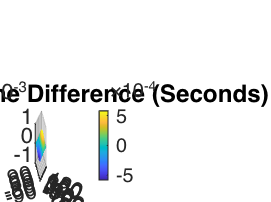

subplot(2,2,3);
[X1,Y1] = meshgrid(-180:5:180,-90:5:90);
Z1 = ICTDTable';
itd = surf(X1,Y1,Z1);
itd.EdgeColor = 'none';
ylim([-90 90]);
xlim([-180 180]);
zlim([-0.001 0.001])
xticks([-180,-150,-120,-90,-60,-30,0,30,60,90,120,150,180])
yticks([-90 -60, -30, 0, 30, 60, 90]);
shading interp
title('Interchannel Time Difference (Seconds)')
xlabel('Azimuth Angle (Deg)')
ylabel('Elevation Angle (Deg)')
zlabel('Time Difference (ms)')
colorbar

clim([-0.001 0.001])

Unrecognized function or variable 'clim'.

## Plot ICTD 2D

ICTD_2D = ICTDTable(:,19)';
sp3 = subplot(2,2,1)
plot([-180:5:180],ICTD_2D,'LineWidth',2, 'Color','b');
xlim([-180 180]);
ylim([-0.001 0.001]);
title('Interchannel Time Difference (elevation = 0°)');
xlabel('Azimuth Angle (Deg)');
ylabel('Time Difference (Sec)');
xticks([-180,-150,-120,-90,-60,-30,0,30,60,90,120,150,180])
%set(sp3,'ContextMenu','XGrid','on','YGrid','on');

## Create Figure ICLD

%figure(3)

## Plot ICLD 3D

subplot(2,2,4);
[X2,Y2] = meshgrid(-180:5:180,-90:5:90);
Z2 = ICLDTable';
icld = surf(X2,Y2,Z2);
icld.EdgeColor = 'none';
ylim([-90 90]);
xlim([-180 180]);
zlim([-20 20]);
xticks([-180,-150,-120,-90,-60,-30,0,30,60,90,120,150,180])
yticks([-90 -60, -30, 0. 30, 60, 90]);
shading interp
title('Interchannel Level Difference (dB)')
xlabel('Azimuth Angle (Deg)')
ylabel('Elevation Angle (Deg)')
zlabel('Level Difference (dB)')
colorbar
clim([-20 20])
GRID('on')

## Plot ICLD 2D

ICLD_2D = ICLDTable(:,19);
sp4 = subplot(2,2,2)
plot([-180:5:180],ICLD_2D, 'LineWidth',2,'Color','r');
xlim([-180 180]);
ylim([-20 20]);
title('Interchannel Level Difference (elevation = 0°)');
xlabel('Azimuth Angle (Deg)');
ylabel('Level Difference (dB)');
xticks([-180,-150,-120,-90,-60,-30,0,30,60,90,120,150,180])
%set(sp4,'ContextMenu','XGrid','on','YGrid','on');
sgtitle(strcat('Simulated Spatial Characteristics of', ' ', ArrayName, ' Microphone Array:', ' ', string(MicSpacing), 'm/', string(MicAngle), '°'));
grid('on')